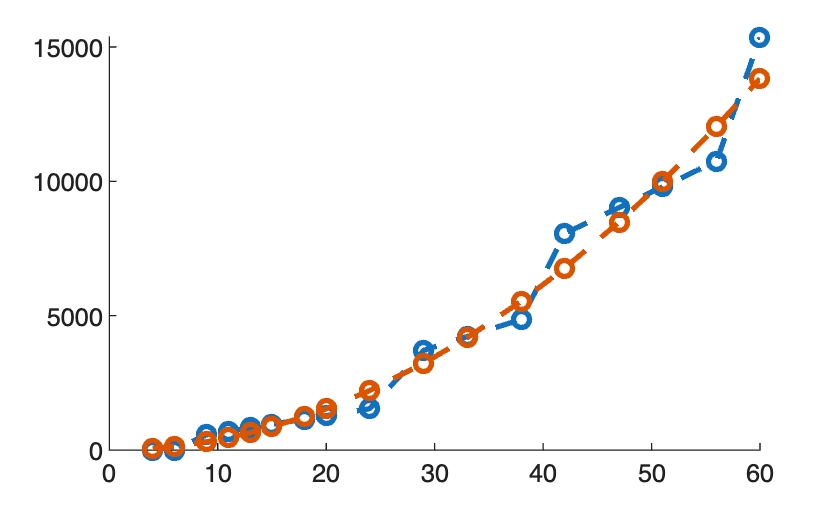

Rout = 0.5;
Rin = 0.1*Rout;
Rbar = (Rout+Rin)/2;
Nr = 166.7;
nSectors = 64;
nRadial = 75;
mesh_size = (Rout-Rin)/nRadial;
nThetaPerSector = round((2*pi*Rbar/nSectors)/mesh_size);
N = nThetaPerSector*nSectors*nRadial;

Nr_max =(Rout-Rin)/0.002;

mb = 20;
temp1 = linspace(4,mb,8);
temp2 = linspace(mb,60,10);
Nr_set = round([temp(1:end-1),temp2]);
mesh_sizes = (Rout-Rin)./Nr_set;
nThetaPerSector = round((2*pi*Rbar/nSectors)./mesh_sizes);
nThetaPerSector2 = (2*pi*Rbar/nSectors)./mesh_sizes;
Nel = nThetaPerSector*nSectors.*Nr_set;
Nel2 = nThetaPerSector2*nSectors.*Nr_set;
figure; hold on;
plot(Nr_set,Nel,"o--","LineWidth",2);
plot(Nr_set,Nel2,"o--","LineWidth",2);
hold off;

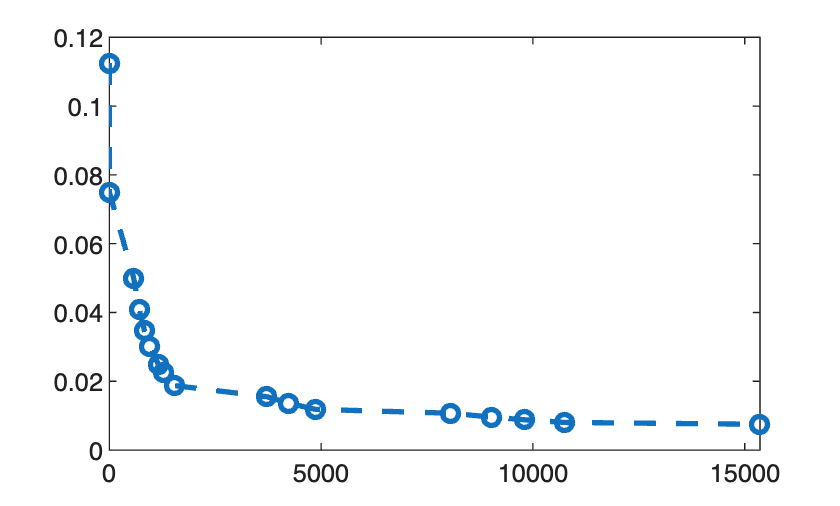

figure
plot(Nel,mesh_sizes,"o--","LineWidth",2);